# Test Case - Power Split Drive Unit

mdl = "PowerSplitDriveUnit_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
PowerSplitDriveUnit_Component_harness_setup

## Setup

simIn = Simulink.SimulationInput(mdl);

% Simulaton stop time
tEnd = "100";
% simIn = setModelParameter(simIn, StopTime = tEnd);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/Road grade", deltaT="0.1");
simIn = setBlockParameter(simIn, mdl+"/Road grade", ...
          dataPoints="[0 1 0; 2 " + tEnd + " 0]");

simIn = setBlockParameter(simIn, mdl+"/Brake force", deltaT="0.1");
simIn = setBlockParameter(simIn, mdl+"/Brake force", ...
          dataPoints="[0 1 0; 2 " + tEnd + " 0]");

simIn = setBlockParameter(simIn, mdl+"/MG2 torque command", deltaT="0.1");
simIn = setBlockParameter(simIn, mdl+"/MG2 torque command", ...
          dataPoints="[0 1 0; 2 " + tEnd + " 0]");

simIn = setBlockParameter(simIn, mdl+"/MG1 torque command", deltaT="0.1");
simIn = setBlockParameter(simIn, mdl+"/MG1 torque command", ...
          dataPoints="[0 10 0; 12 15 9; 16 " + tEnd + " 0]");

simIn = setBlockParameter(simIn, mdl+"/Engine torque command", deltaT="0.1");
simIn = setBlockParameter(simIn, mdl+"/Engine torque command", ...
          dataPoints="[0 13 0; 15 50 80; 52 " + tEnd + " 120]");

% Initial conditions

simIn = setVariable(simIn, "initial.vehicle_speed_kph", 0);

simIn = setVariable(simIn, "initial.engine_speed_rpm", 0);

simIn = setVariable(simIn, "initial.MG1_Temperature_K", 273.15 + 20);
simIn = setVariable(simIn, "initial.MG1_AirTemp_K", 273.15 + 20);

simIn = setVariable(simIn, "initial.MG2_Temperature_K", 273.15 + 20);
simIn = setVariable(simIn, "initial.MG2_AirTemp_K", 273.15 + 20);

% The use of applyToModel below is optional.
% Comment out applyToModel to avoid updating the model file,
% and you can still run simulation.
applyToModel(simIn)

## Run Simulation

% Run simulation
simOut = sim(simIn);

% Copy simlog to the base workspace
% so that sscexplore can load it.
simlog = simOut.simlog;

simData = extractTimetable(simOut.logsout);

## Visualize Simulation Result

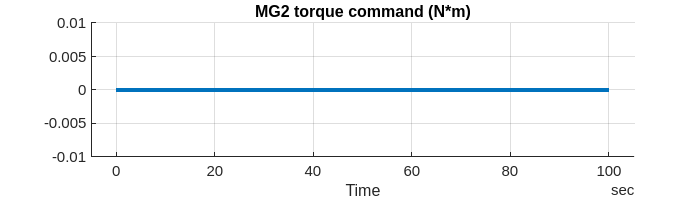

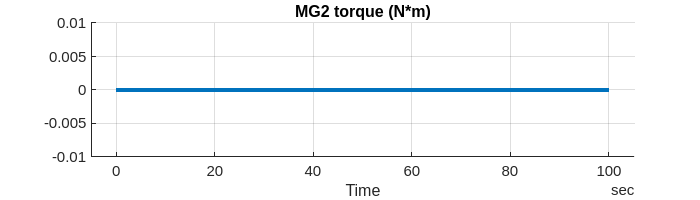

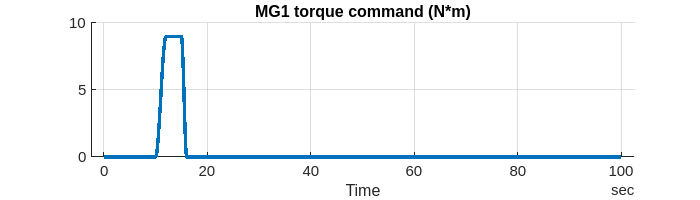

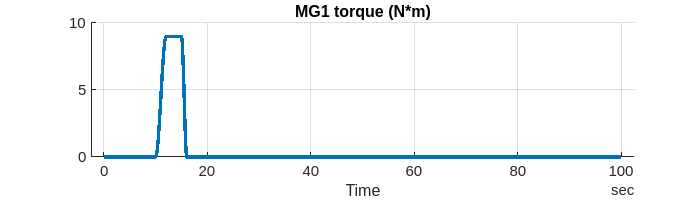

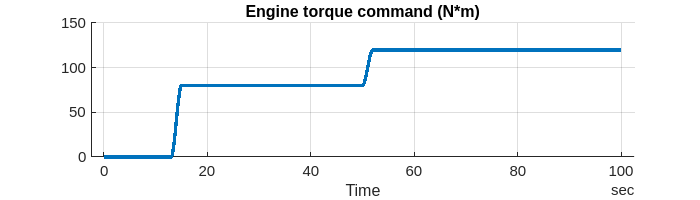

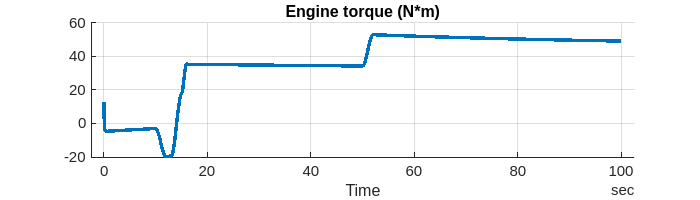

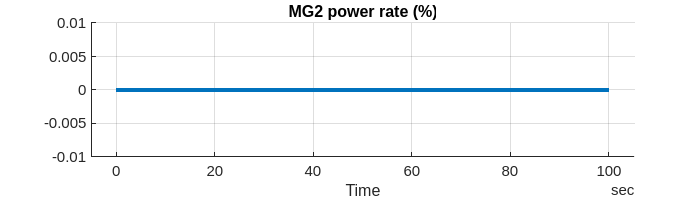

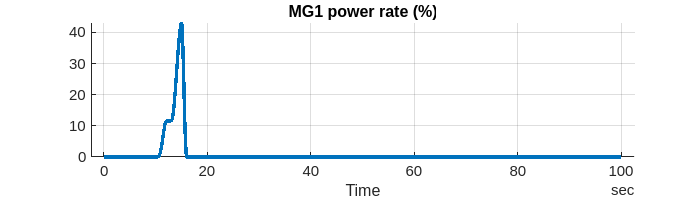

% List of logged signal names.
% See the Measurement subsystem of the model for available signal names.
sigNames = [ ...
  "MG2 torque command", ...
  "MG2 torque", ...
  "MG1 torque command", ...
  "MG1 torque", ...
  "Engine torque command", ...
  "Engine torque", ...
  "MG2 power rate", ...
  "MG1 power rate", ...
  "MG2 speed", ...
  "MG1 speed", ...
  "Engine speed", ...
  "Vehicle speed kph", ...
  "Vehicle speed mph", ...
  "G force", ...
  "Battery SOC" ];

for i = 1 : numel(sigNames)
  fig = plotSimulationResultSignal(SimData = simData, SignalName = sigNames(i));
  fig.Position(4) = 200;
end

*Copyright 2021-2022 The Mathworks, Inc.*